clear all

#### **README**:

- For running this code, you will require to have all functions and required .m files. Please copy them from: "*pathway*" to the directory of your files. 

- This code is still not automated for looping all subjects and has to be run for each task and each subject separately.

- This code will get the segmented walking task (10m, 2min, 6min) in the .m format and export a table with 51 parameters as columns and each stride as row. 

%load the parameter labels 
load('Parameters.mat');
%load the structure - Change when needed
data = load('HC01_10MWT_F_1_Segmented.mat');
%Export table with strides as rows and parameters as columns 
Exportparameters = array2table(nan(max(size(data.subdata_out.Segmented.Lseg.ACC_seg,1), size(data.subdata_out.Segmented.Rseg.ACC_seg, 1)),numel(Parameters)),'VariableNames', Parameters);
%assigned body sides in the structure
bodyside = {'Lseg','Rseg'};
footcontact = readtable('footContacts.csv');

# **Pre-Processing Visual Inspection**

**In this section you can look at the plots of right and left strides. We should avoid having outliers as much as possible. So, always make sure to mark odd strides and body sides.**

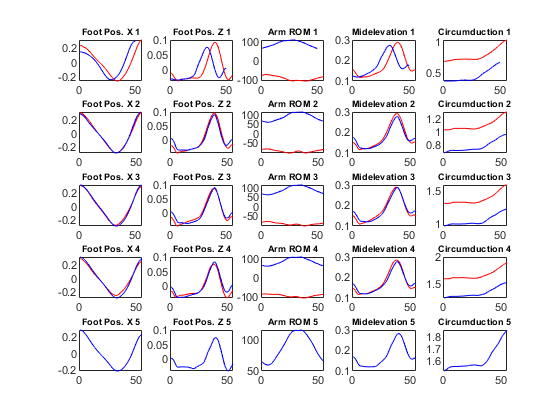

dataL = data.subdata_out.Segmented.Lseg;
dataR = data.subdata_out.Segmented.Rseg;
figure;

% Determine the number of rows for subplots (based on max rows between dataL and dataR)
numRows = max(size(dataL.PosFiltered_seg, 1), size(dataR.PosFiltered_seg, 1));

for i = 1:numRows
    % Plot 5 columns for each row
    subplot(numRows, 5, (i - 1) * 5 + 1);
    if i <= size(dataL.PosFiltered_seg, 1)
        plot(dataL.PosFiltered_seg{i, 7}, 'r');  % Plot data from dataL if it exists
        hold on;
    end
    if i <= size(dataR.PosFiltered_seg, 1)
        plot(dataR.PosFiltered_seg{i, 4}, 'b');  % Plot data from dataR if it exists
    end
    hold off;
    title(sprintf('Foot Pos. X %d', i), 'FontSize', 7);  
    
    subplot(numRows, 5, (i - 1) * 5 + 2);
    if i <= size(dataL.PosFiltered_seg, 1)
        plot(dataL.PosFiltered_seg{i, 9}, 'r');
        hold on;
    end
    if i <= size(dataR.PosFiltered_seg, 1)
        plot(dataR.PosFiltered_seg{i, 6}, 'b');
    end
    hold off;
    title(sprintf('Foot Pos. Z %d', i), 'FontSize', 7); 
    
    subplot(numRows, 5, (i - 1) * 5 + 3);
    if i <= size(dataL.Q_seg, 1)
        plot(dataL.Q_seg{i, 58}, 'r');
        hold on;
    end
    if i <= size(dataR.Q_seg, 1)
        plot(dataR.Q_seg{i, 46}, 'b');
    end
    hold off;
    title(sprintf('Arm ROM %d', i), 'FontSize', 7);
    
    subplot(numRows, 5, (i - 1) * 5 + 4);
    if i <= size(dataL.Pos_seg, 1)
        plot(dataL.Pos_seg{i, 9}, 'r');
        hold on;
    end
    if i <= size(dataR.Pos_seg, 1)
        plot(dataR.Pos_seg{i, 6}, 'b');
    end
    hold off;
    title(sprintf('Midelevation %d', i), 'FontSize', 7);
    
    subplot(numRows, 5, (i - 1) * 5 + 5);
    if i <= size(dataL.Pos_seg, 1)
        plot(dataL.Pos_seg{i, 8}, 'r');
        hold on;
    end
    if i <= size(dataR.Pos_seg, 1)
        plot(dataR.Pos_seg{i, 5}, 'b');
    end
    hold off;
    title(sprintf('Circumduction %d', i), 'FontSize', 7);
end

# **Calculating Cadence (step/min)**

This code basically measures the duration of each step (Instantenous cadence) and connects to number of multiple steps per minute. 

Note: For sure we always need an inspection! 

%Calculating Cadence (step/min) and Cadence Assym (%)
Exportparameters = Cadence(data, bodyside, Exportparameters);

# **Calculating Stance, Swing, Single, and Double Support (%GCT)**

%Calculating Stance, Swing, SS, and DS (all %GCT) and their assymetries (%)
Exportparameters = SSSD(data, bodyside, footcontact, Exportparameters);

# **Calculating Step Length (m)**

%Calculating step length (m) and step length assymetry (%)
Exportparameters = StepLength(data, bodyside, Exportparameters);

# **Calculating Step Duration (s) and Velocity (m/s) **

%Calculating Step duration (s), step velocity (m/s), assymetries (%)
Exportparameters = DurationSpeed(data, bodyside, footcontact, Exportparameters);

# **Calculating Midswing Elevation (m) and Circumduction (m)**

%Calculating midswing elevation (m) and circumduction (m) and their assymetries (%)
Exportparameters = ElevationCircumduction(data, bodyside, Exportparameters);

# **Calculating Toe Off, FootStrike, and Toe Out angles (degrees)**

%Calculating ToeOff, FootStrike, ToeOut angles (degrees), assymetries (%)
Exportparameters = ToeAngles(data, bodyside, footcontact, Exportparameters);

# **Calculating Lumbar and Trunk ROM (X, Y, Z; degrees)**

%Calculating Lumbar and Trunk ROM (degrees)
Exportparameters = LumbarTrunk(data, Exportparameters);

# **Calculating Arm Swing Velocity (radian/s) and ROM (degrees) and Assymetries (%)**

%Calculating Arm Swing Velocity (radian/s) and ROM (degrees)
Exportparameters = Arm(data, Exportparameters);

# **Saving the Gait Parameters**

transposedData = Exportparameters.Variables';
numColumns = size(transposedData, 2);
dynamicColumnNames = strcat('Stride', string(1:numColumns));
newExportparameters = array2table(transposedData, 'VariableNames', dynamicColumnNames);
newExportparameters = addvars(newExportparameters, Parameters', 'Before', 1, 'NewVariableNames', 'Parameter');
writetable(newExportparameters, 'Exportparameters.csv');
